Extract pre-recorded data. IMPORTANT: change path name to the path of test data on your computer

path = "C:\Users\shobh\OneDrive\Desktop\timed_readings.txt";
mpudata = readtable(path);
mpudata.Properties.VariableNames = ["Time", "GyroX", "GyroY", "GyroZ", "AccelX", "AccelY", "AccelZ"]

mpudata = 391×7 table
    Time    GyroX    GyroY    GyroZ    AccelX    AccelY    AccelZ
    ____    _____    _____    _____    ______    ______    ______

    0.01    -0.28    -0.08    0.23      0.09         0      0.88 
    0.21    -0.31     0.01    0.21      0.09         0      0.89 
    0.42    -0.28    -0.16    0.24      0.09         0      0.89 
    0.62     -0.3     0.25    0.22      0.09      0.01      0.89 
    0.83    -0.27    -0.27    0.23      0.09      0.01      0.88 
    1.03    -0.28     0.14    0.22      0.09         0      0.88 
    1.24    -0.29     0.02    0.23      0.09         0      0.89 
    1.44     -0.3    -0.11    0.21      0.09      0.01      0.88 
    1.65    -0.31     0.19    0.24      0.09         0      0.88 
    1.86    -

Lets see how the GyroX data looks

plot(mpudata.Time, mpudata.GyroX, "b")
hold on
OrientX = zeros(392,1);
for c = 2:392
    OrientX(c) = mpudata.Time(c-1)*mpudata.GyroX(c-1);
end
plot(mpudata.Time, OrientX(1:391), "r")
xlabel("Time [s]")
ylabel("Degrees")
legend("readingX", "orientationX")
hold off

Not much insight (rather than the curve slanting downwards), but lets look at the first 20 seconds or so when the sensor is supposed to be stationary

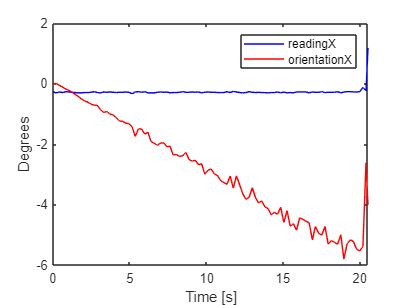

xlim([0 20.5])

This is when the sensor drift (or bias) becomes apparent. Even in a stationary setting, the sensor seems to indicate that there is some rotation in the x-direction. Let us look at the other axes as well.

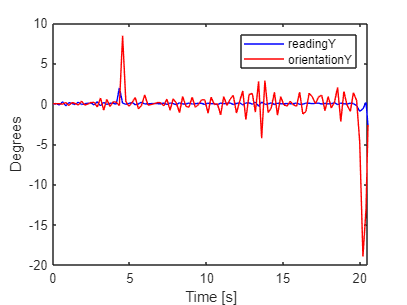

OrientY = zeros(392,1); OrientZ = zeros(392,1);
for c = 2:392
    OrientY(c) = mpudata.Time(c-1)*mpudata.GyroY(c-1);
    OrientZ(c) = mpudata.Time(c-1)*mpudata.GyroZ(c-1);
end

plot(mpudata.Time, mpudata.GyroY, "b")
hold on
plot(mpudata.Time, OrientY(1:391), "r")
legend("readingY", "orientationY")
xlim([0 20.5])
xlabel("Time [s]")
ylabel("Degrees")
hold off

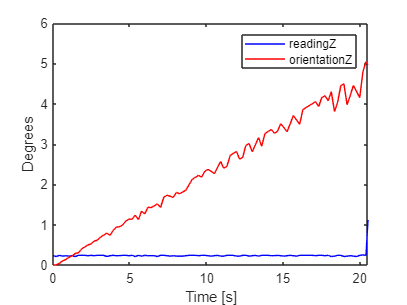


plot(mpudata.Time, mpudata.GyroZ, "b")
hold on
plot(mpudata.Time, OrientZ(1:391), "r")
legend("readingZ", "orientationZ")
xlim([0 20.5])
xlabel("Time [s]")
ylabel("Degrees")
hold off

From this we can see that GyroX has a negative bias, GyroY has a neutral (?) bias, and GyroZ has a positive bias. How do we fix thisssssss?